# Metarate example

This script provides examples of how the functions in this repository can be used to:

- calculate rate measures using the proportional duration summation method

- conduct a scalographic analysis

- plot a scalogram and a difference of scalograms

The workflow used to conduct analyses for the paper "Parameters of unit-based measures of speech rate" is documented in `metarate_workflow.mlx`.

## Setup

To run this script you should be in the `MetaRate` repository directory.

if ~contains(pwd,'MetaRate')
    fprintf('WARNING: current directory should be the top-level directory of the MetaRate repository\n');
return
end

Add all sub-directories of the respository to the path:

addpath(genpath('.'));

Two inputs are necessary for our scalographic analyses:

- The proportional durations table.

- The targets data table.

## Proportional durations table

This is table that contains the proportional duration (or proportional unit count) timeseries for each utterance. Here we use `example_propdurs_table.mat`, which is based on segmented utterances from a single speaker (F01) from the HPRC corpus. It can be found in the `examples` subdirectory of this repository.

load('example_propdurs_table.mat');
head(TR);

     subj      block    sent    rep    rate                          text                             words                                        words_t0                                                                          words_t1                                          phones                                                                                           phones_t0                                                                                                                                                                              phones_t1                                                                                                trcode                  fname                                       phones_words_ix

#### Unit-based segmentations

At least one unit-based segmentation of each utterance is needed. Here our utterances are associated with arrays of unit labels, such as phones and words:

list_of_phones = TR.phones{1}

list_of_phones = 1×29 cell array
    {'sp'}    {'DH'}    {'AH0'}    {'B'}    {'ER1'}    {'CH'}    {'K'}    {'AH0'}    {'N'}    {'UW1'}    {'S'}    {'L'}    {'IH1'}    {'D'}    {'AA1'}    {'N'}    {'DH'}    {'IY0'}    {'S'}    {'M'}    {'UW1'}    {'DH'}    {'P'}    {'L'}    {'AE1'}    {'NG'}    {'K'}    {'S'}    {'sp'}


list_of_words = TR.words{1}

list_of_words = 1×10 cell array
    {'sp'}    {'THE'}    {'BIRCH'}    {'CANOE'}    {'SLID'}    {'ON'}    {'THE'}    {'SMOOTH'}    {'PLANKS'}    {'sp'}


The start and end times of each unit (here relative to the beginning of the recording) must be included as well, e.g.:

vector_of_phone_start_times = TR.phones_t0{1}

vector_of_phone_start_times =          0    0.2000    0.2499    0.2898    0.3596    0.4594    0.5293    0.5991    0.6290    0.6889    0.7288    0.8485    0.9084    0.9383    0.9782    1.0281    1.0580    1.0880    1.1179    1.2476    1.2975    1.4073    1.4372    1.5270    1.6068    1.6367    1.6667    1.7365    1.8762


vector_of_phone_end_times = TR.phones_t1{1}

vector_of_phone_end_times =     0.2000    0.2499    0.2898    0.3596    0.4594    0.5293    0.5991    0.6290    0.6889    0.7288    0.8485    0.9084    0.9383    0.9782    1.0281    1.0580    1.0880    1.1179    1.2476    1.2975    1.4073    1.4372    1.5270    1.6068    1.6367    1.6667    1.7365    1.8762    2.0762


In addition, maps between units at different levels must be included (if one wants to use a rate unit that differs from the target unit)

%the integer indices of words for each phone:
indices_of_words_byphone = TR.phones_words_ix{1}

indices_of_words_byphone =      1     2     2     3     3     3     4     4     4     4     5     5     5     5     6     6     7     7     8     8     8     8     9     9     9     9     9     9    10


%the integer indices of phones for each word:
indices_of_phones_byword = TR.words_phones_ix{1}

indices_of_phones_byword = 1×10 cell array
    {[1]}    {[2 3]}    {[4 5 6]}    {[7 8 9 10]}    {[11 12 13 14]}    {[15 16]}    {[17 18]}    {[19 20 21 22]}    {[23 24 25 26 27 28]}    {[29]}


#### Calculating proportional the proportional duration timeseries

Use the function `metarate_calc_prop_durs`  as shown below, to calculate the timeseries of proportional durations (or proportional unit counts) for a given type of unit, and add these to the proportional durations table:

unit = 'words';
dt = 0.001;

for i=1:height(TR)

    %calculates frame time-points, proportional counts, and indices
    [frpnts,prop_dur,UIX] = metarate_calc_prop_durs(TR(i,:),unit,dt);

    %add the outputs to the table:
    TR.frt{i} = frpnts; 
    TR.([unit '_pdur']){i} = prop_dur;
    TR.([unit '_pdur_map']){i} = uint8(UIX);     %max of 256 different units in utterance
end

A proportional unit count timeseries looks like this:

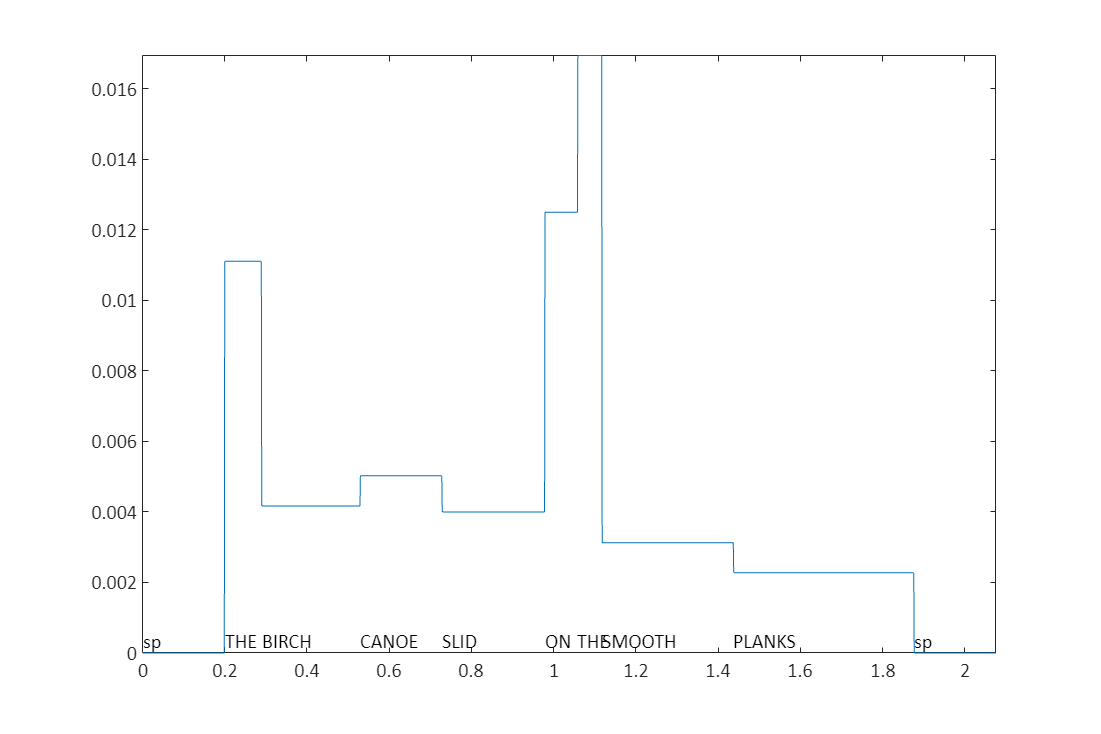

figls; plot(TR.frt{1},TR.words_pdur{1}); 
for i=1:length(TR.words{1}), text(TR.words_t0{1}(i),0,TR.words{1}{i},'verti','bot'); end
axis tight;

## Target data table

A table of target variables is needed.

load('example_targets_table.mat','D');

This table contains the duration of each phone, along with its start and end times, its midpoint, and its index (in the utterance):

info_target_phone = head(D(:,{'phones' 'dur' 't0' 't1' 'tmid' 'ix'}))

info_target_phone = 8×6 table
    phones      dur         t0         t1        tmid      ix
    ______    ________    _______    _______    _______    __

    {'B'}     0.069841     0.2898    0.35964    0.32472     4
    {'P'}     0.089796     1.4372      1.527     1.4821    23
    {'B'}     0.099773    0.26984    0.36961    0.31973     4
    {'P'}     0.089796     1.9161     2.0059      1.961    23
    {'B'}     0.079819    0.27982    0.35964    0.31973     4
    {'P'}     0.089796      1.976     2.0658     2.0209    24
    {'B'}     0.029932      1.058      1.088      1.073    18
    {'B'}     0.059864     1.1977     1.2576     1.2277    21


The table also contains information about the higher-level units that contain the phones:

head(D(:,{'words' 'words_t0' 'words_t1'}))

        words         words_t0    words_t1
    ______________    ________    ________

    {'BIRCH'     }     0.2898     0.52925 
    {'PLANKS'    }     1.4372      1.8762 
    {'BIRCH'     }    0.26984     0.61905 
    {'PLANKS'    }     1.9161       2.405 
    {'BIRCH'     }    0.27982     0.59909 
    {'PLANKS'    }      1.976      2.4549 
    {'BLUE'      }      1.058      1.1977 
    {'BACKGROUND'}     1.1977      1.6667 



## Scalographic analysis

#### Required inputs

The function `metarate_scalographic_analysis` conducts a scalographic analysis. It requires a table of proportional durations and a table of targets (both described above). 

#### Analysis parameters

The function takes the following parameters:

**data_selection**

- 'bytarget' (default): use only datapoints that fit in all rate-estimation windows

- 'bywindow': for a given rate-estimation window, use whatever datapoints fit in that window

**target_exclusion**

- true (default): exclude from the rate-estimation window the rate-unit that contains the target

- false: do not exclude the target-containing rate unit

**window_method**

- 'centered' (default): windows are centered on target units

- 'beginanchored': windows are left-aligned to ends of target units

- 'endanchored': windows are right-aligned to beginnings of target units

- 'extendwin': centered windows which are extended to compensate for exclusion

- 'adaptivewin': windows which are shifted to remain within utterance

Please see [./metarate_windef_methods.mlx](matlab:open('./metarate_windef_methods.mlx')) for examples of the above window methods.

**unit**

This is the unit used for calculating rate. The  default is "phones". The name of the unit must correspond to fields in both the proportional durations table and the targets table. 

Specifically:

- The proportional durations table must contain a field with the unit name suffixed by '_pdur'. For example if "words" is the rate unit, the proportional durations table must contain a column named 'words_pdur'.

- The targets data table must contain columns that indicated start/end times of the rate unit. For example if "words" is the rate unit, the targets data table must contain columns named 'words_t0' and words_t1'.

head(D(:,{'phones' 'fname' 'words_t0', 'words_t1'}));

    phones            fname            words_t0    words_t1
    ______    _____________________    ________    ________

    {'B'}     {'F01_B01_S01_R01_F'}     0.2898     0.52925 
    {'P'}     {'F01_B01_S01_R01_F'}     1.4372      1.8762 
    {'B'}     {'F01_B01_S01_R01_N'}    0.26984     0.61905 
    {'P'}     {'F01_B01_S01_R01_N'}     1.9161       2.405 
    {'B'}     {'F01_B01_S01_R02_N'}    0.27982     0.59909 
    {'P'}     {'F01_B01_S01_R02_N'}      1.976      2.4549 
    {'B'}     {'F01_B01_S02_R01_F'}      1.058      1.1977 
    {'B'}     {'F01_B01_S02_R01_F'}     1.1977      1.6667 



The function checks whether these conditions hold and returns an error otherwise.

**inverse_rate**

- 2 (default): return correlations from both proper and inverse rates

- 0: return correlations based on proper rates

- 1: return correlations based on inverse rates

**Additional parameters:**

- frame_per (default = 0.001 s): the frame period. This must match the period of the proportional duration timeseries in the proportional durations table.

- scale_range: the range of scales to analyze. By default, these are defined differently for different window methods within the function. 

- center_range: the range of centers to analyze. By default, these are defined differently for different window methods within the function. 

- scale_step (default = 0.050 s): the step sizes for defining window sizes to analyze.

- center_step (default = 0.025 s): the step size for defining window centers to analyze.

- target_ident_field (default = 'phones'): the name of the targets data table column that encodes the identity of the target units

- target_variable (default = 'dur'): the name of the targets data table column that encodes the dependent variable of the partial correlation

- return_datasets (default = 'false'): returns extra data for debugging

- use_parallel (default = 'false'): parallelizes some aspects of the scalographic analysis. currently only provides minor speedups.

- n_threads (default = 6): number of threads to use for parallelized analysis.

#### **Running the function**

Here is an example of how the function is run

datasel = 'bytarget';  %use the same data-points across windows
target_exclusion = true;
winmethod = 'extendwin'; %extend windows to compensate for excluded rate unit
unit = 'words';

T = metarate_scalographic_analysis(TR,D,...
    'unit',unit,...
    'target_exclusion',true,...
    'data_selection',datasel,...
    'window_method',winmethod);

The output of `metarate_scalographic_analysis` is a table that contains various information about each analysis.

Included in the output is the partial correlation (rho), the p-value of the partial correlation, the rate measure used, the target variable name, the data selection strategy, the target exclusion parameter, the ratio expression (1 for inverse, 0 for proper), the number of tokens in the analysis, the number for which the rate measure was non-finite, the number for which an NaN value was observed, and the total number of valid tokens in the analysis:

head(T(:,{'rho' 'pval' 'target' 'unit' 'scale' 'center' 'winmethod'}))

       rho         pval         target        unit       scale    center      winmethod  
    _________    _________    __________    _________    _____    ______    _____________

     -0.12695    0.0070074    {'phones'}    {'words'}    0.05     -0.475    {'extendwin'}
     -0.08038     0.088188    {'phones'}    {'words'}    0.05      -0.45    {'extendwin'}
    -0.098098     0.037082    {'phones'}    {'words'}     0.1      -0.45    {'extendwin'}
    -0.055062      0.24269    {'phones'}    {'words'}    0.05     -0.425    {'extendwin'}
     -0.10044     0.032764    {'phones'}    {'words'}     0.1     -0.425    {'extendwin'}
      -0.1448    0.0020271    {'phones'}    {'words'}    0.15     -0.425    {'extendwin'}
    -0.097698     0.037865    {'phones'} 

head(T(:,{'datasel' 'exclusion' 'inversion' 'N_tokens' 'N_inf' 'N_nan' 'N_valid'}))

      datasel       exclusion    inversion    N_tokens    N_inf    N_nan    N_valid
    ____________    _________    _________    ________    _____    _____    _______

    {'bytarget'}      true           0          453         2        0        451  
    {'bytarget'}      true           0          453         1        0        452  
    {'bytarget'}      true           0          453         0        0        453  
    {'bytarget'}      true           0          453         0        0        453  
    {'bytarget'}      true           0          453         0        0        453  
    {'bytarget'}      true           0          453         0        0        453  
    {'bytarget'}      true           0          453         0        0        453  
    {

## Plotting a scalogram

First prepare the scalographic information for plotting:

S = params_from_scalographs(T);
S(1)

ans = struct with fields:
       target: 'phones'
         unit: 'words'
      datasel: 'bytarget'
    winmethod: 'extendwin'
    exclusion: 1
    inversion: 0


The function "prep_subsets" takes a cell array of structures with analysis parameters as input:

G = prep_subsets({S(1)});
G(1).subset

ans = struct with fields:
       target: 'phones'
         unit: 'words'
      datasel: 'bytarget'
    winmethod: 'extendwin'
    exclusion: 1
    inversion: 0


The function `prep_scalographs` generates a structure (with one element for each scalograph) with the centers (XX), scales (YY), and scalogram values (ZZ).

SC = prep_scalographs(T,G)

SC = struct with fields:
            XX: [951×1 double]
            YY: [191×1 double]
        varlab: '{\it{r}}^{\prime}'
            ZZ: [191×951 double]
     rho_range: [-0.1212 0.2642]
         clims: [-0.1222 0.2652]
          cmap: [5001×3 double]
    rho_levels: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
        panlab: 'phones \sim word/s'
         ax_ix: 1


Plot scalographs can be used to plot a set of scalographs in a set of axes:

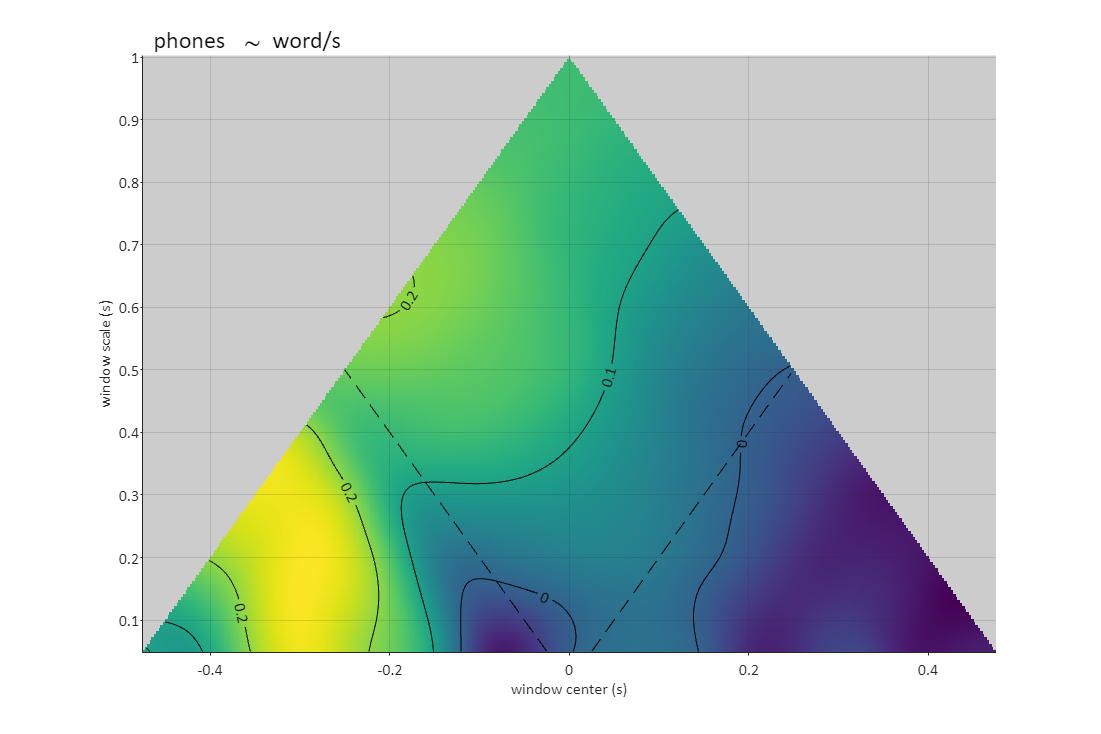

figls; plot_scalographs(SC,gca);

## Plotting a difference scalogram

First, let's conduct separate scalographic analyses on the /p/ and /b/ phones from our example dataset:

% make separate data tables
D_p = D(ismember(D.phones,{'P'}),:);
D_b = D(ismember(D.phones,{'B'}),:);

%define analysis parameters
params = {...
    'unit','words',...
    'target_exclusion',true,...
    'window_method','extendwin',...
    'inverse_rate',0};

%conduct scalographic analyses
T_p = metarate_scalographic_analysis(TR,D_p,params{:});
T_b = metarate_scalographic_analysis(TR,D_b,params{:});

%rename target fields and combine:
T_p.target = repmat({'phone_p'},height(T_p),1);
T_b.target = repmat({'phone_b'},height(T_b),1);

T = [T_p; T_b];

Now let's prepare all three scalograms and plot:

S = params_from_scalographs(T);

S(1)

ans = struct with fields:
       target: 'phone_b'
         unit: 'words'
      datasel: 'bytarget'
    winmethod: 'extendwin'
    exclusion: 1
    inversion: 1


S(2)

ans = struct with fields:
       target: 'phone_p'
         unit: 'words'
      datasel: 'bytarget'
    winmethod: 'extendwin'
    exclusion: 1
    inversion: 1


G = prep_subsets({S(1),S(2),S});
SC = prep_scalographs(T,G);

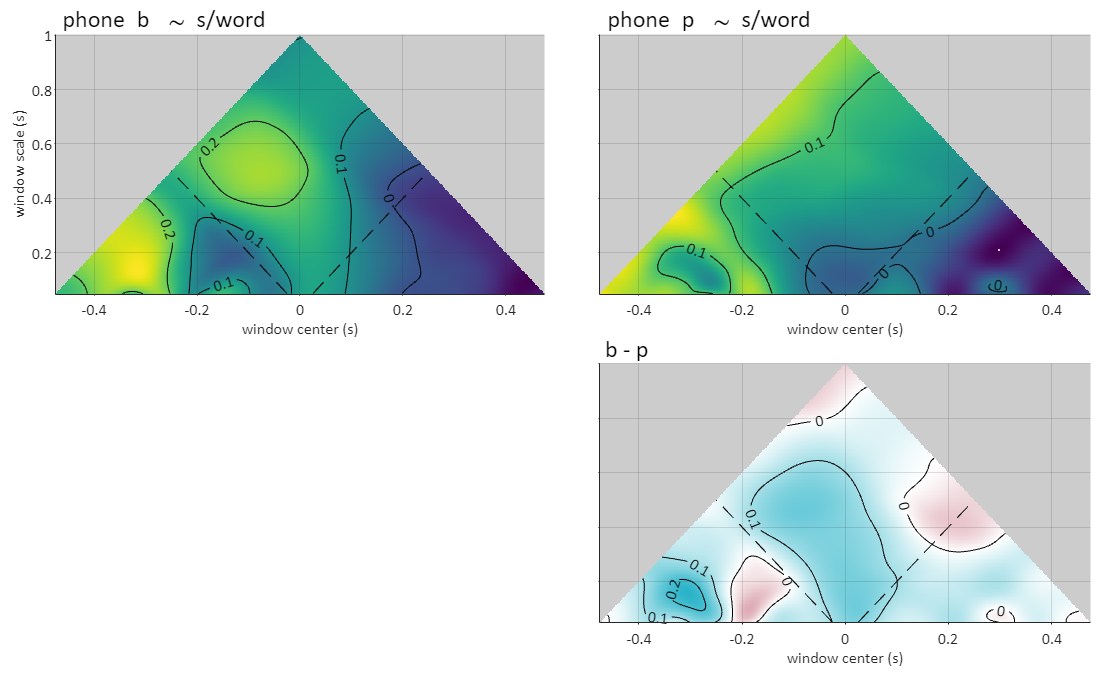

figls; ax = stf([1 2; nan 3],[0.05 0.10 0.01 0.05],[0.05 0.10],'parent',gcf); %creates a figure with some axes
handles = plot_scalographs(SC,ax);
handles.th(end).String = 'b - p';

function [] = figls()
figure('units','pixels','outerposition',[0 0 750 500]);
end